# Da Nang University Of Science and Technology - CompEng - Tran Viet Thang

## Mosaic image

clc ; 
clear all ;
close all ; 
% we first read an original image
I = imread("kodim19.png") ; 
bayer_CFA_image = zeros(size(I)) ; 
% red color 
bayer_CFA_image(1:2:end,1:2:end,1) = I(1:2:end,1:2:end,1) ; 
% blue color 
bayer_CFA_image(2:2:end,2:2:end,3) = I(2:2:end,2:2:end,3) ;
% green color 
bayer_CFA_image(1:2:end,2:2:end,2) = I(1:2:end,2:2:end,2) ; 
bayer_CFA_image(2:2:end,1:2:end,2) = I(2:2:end,1:2:end,2) ; 
% show image 
bayer_CFA_image = uint8(bayer_CFA_image); 

## Zero padding green image

[H,W,~] = size(I) ; 
gr_image = zeros([H,W]) ;
gr_image = bayer_CFA_image(:,:,2) ; 
% zero padding green image
ze_pad_gr_img= zeros([H+2,W+2]) ;
ze_pad_gr_img(2:1:H+1,2:W+1) = gr_image(1:1:H,1:1:W) ;

## Interpolation green channel image

inter_gr_img = zeros([H,W]) ;
para_e = 0.5 ;
for v_idx = 2 :1: H+1 
    for h_idx = 2 :1: W+1 
       v_mod_2 = mod(v_idx,2) ; % only return value <2 -> 0 : even , 1 : odd
       h_mod_2 = mod(h_idx,2) ; % only return value <2 -> 0 : even , 1 : odd
       flag = xor(v_mod_2,h_mod_2) ; % return 1 if var_1 != var_2 (binary value)
       if(flag==1) 
           inter_gr_img(v_idx-1,h_idx-1) = ze_pad_gr_img(v_idx,h_idx) ;
       else
       % extracting 4 point 
          top_point    = ze_pad_gr_img(v_idx+1,h_idx) ; 
          bottom_point = ze_pad_gr_img(v_idx-1,h_idx) ; 
          left_point   = ze_pad_gr_img(v_idx,h_idx-1) ; 
          right_point  = ze_pad_gr_img(v_idx,h_idx+1) ; 
          diff_V   = abs(top_point-bottom_point) ; % dental H 
          diff_H   = abs(right_point-left_point) ; % dental V 
          if(diff_H+para_e<diff_V) 
              inter_gr_img(v_idx-1,h_idx-1) = (left_point+right_point)./2 ;
          else if(diff_V+para_e<diff_H)
               inter_gr_img(v_idx-1,h_idx-1) = (top_point+bottom_point)./2 ; 
          else 
               inter_gr_img(v_idx-1,h_idx-1) = (top_point+left_point+right_point+bottom_point)./4; 
          end
          end
      end
    end
end 
%show image 

## Reconstructe Red and Blue channel

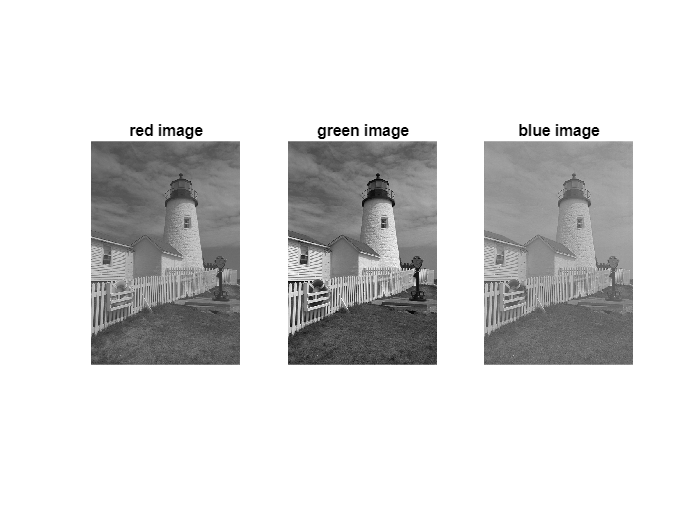

mR = zeros([H,W]) ;  % red matrix
mB = zeros([H,W])  ; % blue matrix 
mR(1:2:end,1:2:end) = 1 ; 
mB(2:2:end,2:2:end) = 1 ;
F_r_b = [1 2 1;2 4 2;1 2 1]/4; % kernel for bilinear interpolation
% reconstructe red channel 
Rd  = double(bayer_CFA_image(:,:,1))-inter_gr_img ;
Rd1 = Rd.*mR ; 
Rd2 = conv2(Rd1,F_r_b,'same') ;  
r_img = Rd2 + inter_gr_img; 
% reconstructe blue channel 
Bd = double(bayer_CFA_image(:,:,3))-inter_gr_img ; 
Bd1 = Bd.*mB; 
Bd2 = conv2(Bd1,F_r_b,'same') ; 
bl_img = Bd2 + inter_gr_img ; 
gr_img = inter_gr_img ; 
clc ; 
close all ; 
subplot(1,3,1) ; imshow(r_img,[]) ; title('red image') ; 
subplot(1,3,2) ; imshow(gr_img,[]) ; title('green image') ; 
subplot(1,3,3) ; imshow(bl_img,[]) ; title('blue image') ; 

## Reconstructe image

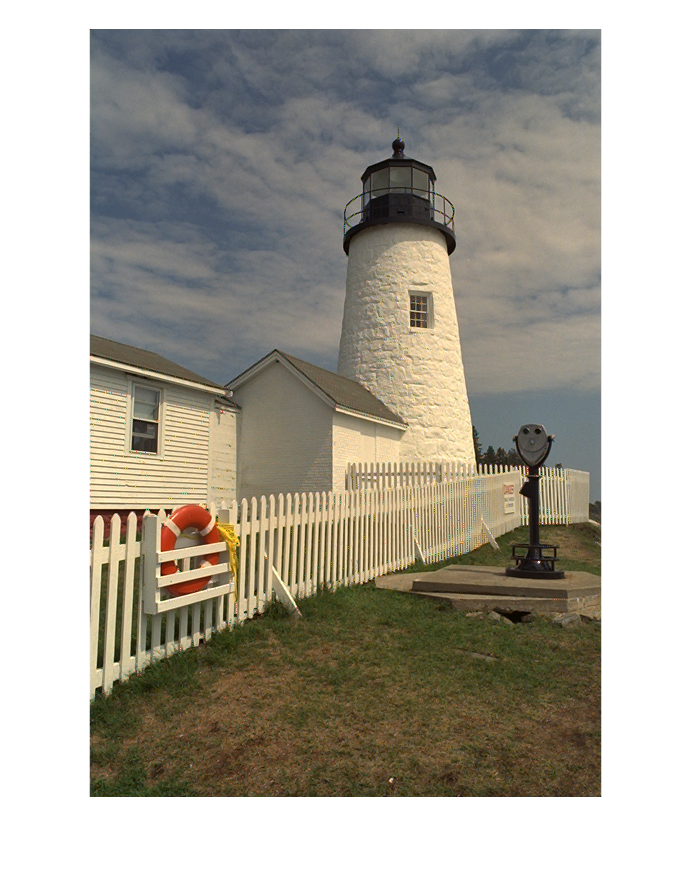

recon_img = zeros(size(I));
recon_img(:,:,1) = r_img ; 
recon_img(:,:,2) = gr_img ; 
recon_img(:,:,3) = bl_img ;
recon_img = uint8(round(recon_img)) ; 
clc ; 
close all  ;
imshow(recon_img) ;

psnr = PSNRCAL(I,recon_img) 

psnr = 33.1266